clear; close all, clc
% this is the true aether buisness jet desinged for the AIAA 2025 design
% competition
% note that insufficiently many lateral flap sections exist. at least 3
% spanwise flap sections are recomended per wing for desired lateral
% response.

% this is cals model
% currently roughly trimmed

%THings to implement and fix
% moment- flaps are not at cg
% moment - flaps have an impact on aircraft moment
% delay in downwash gradient - deplison/dalpha due to flaps
% acceleration of an offset seat (include rotation)
% adjust acceleration to actually refer to body accelerations for correct
% computaiton of ride quality

% to add as parameters. ->
% initial flap angle
% aerodynamic hinge moment

## Define the simulation parameters

dt = .01; % time step (seconds)
dt_turbulence = .1; % seconds - must be an integer multiple of dt
t_total = 25

t_total = 25

0 % total simulation time (seconds)

ans = 0

time = [0:dt:t_total]';
angle = 5; % perturbed deflection (degrees)

disable_PAH = false; % use rigid flap?

k_command = .2; % comanded value of spring stiffness (N/m)
c_r_command = .05; % comanded value of rate damping ()
c_c_command = .005; % commanded value of coulomb damping ()
delt_0_command = deg2rad(5); % comanded value of deflection (rad)

I_flap = .9; % moment of inertia of flap about hinge line (kg*m^4)

% Dryden turbulence parameters (modify as needed)
altitude = convlength(46000,"ft","m");     % Initial altitude (m)
windspeed_20ft = 30;   % Wind speed at 20 ft (m/s)
v_avg = convvel(487.542331889981,"kts","ft/s"); % average vehicle speed
turbulence_intensity = 'severe'; % 'light', 'moderate', or 'severe'
b    = convlength(76.80,"ft","m"); %(ft)

% Generate Dryden gust velocities
[ug, vg, wg] = generate_dryden_gust(time, altitude, v_avg, turbulence_intensity, 1/dt);
vg = zeros(size(ug));

% try the rotational gusts as well
[ug, vg, wg, pg, qg, rg] = generate_dryden_gust_with_rotational( ...
    time, altitude, v_avg, windspeed_20ft, "severe", b/2, 1/dt_turbulence);
vg = zeros(size(ug));
pg = zeros(size(ug));
rg = zeros(size(ug));

%for step response
% ug = zeros(size(ug));
% wg = zeros(size(ug));
% qg = zeros(size(ug));
% gust_on = floor(.1*length(wg));
%wg(gust_on:end) = ones(1,length(wg)-gust_on+1) .* v_avg * -tan(5);
%wg((1/dt:1.5/dt)) = ones(size(1/dt:1.5/dt)).*angle.*pi./180;

% gust_velocities = [ug;vg;wg];
gust_velocities = [ug; vg; wg; pg; qg; rg];
gust_velocities(1:3,:) = convvel(gust_velocities(1:3,:), "m/s", "ft/s");
gust_velocities = resample(gust_velocities', dt_turbulence/dt,1)'; % resample from 10Hz (as required by the mil spec) to the simulation rate 100Hz



% these are good if the initial flap angle is zero
x_0 = [k_command, c_r_command, c_c_command, delt_0_command, I_flap];
x_0 = [.2, .05, .0005, .087266, .9]; % pretty good values - optimal for the c310
x_0 = [-0.0518, 43.6289, 0.0005, 85.1409, 1.4451]; % optimal over 20 second window (very good)
x_0 = [0.6773, 11.2789, 0.0004, -2.0731, 16.5946]; % less optimal over 20 second window but positive
% x_0 = [0.6773, 11.2789, 0.0004, 0, 16.5946]; % modified?
% x_0 = [-6.8349, 14.5220, 0.0004, 0.7776, 7.4999]; % optimal over 150 seconds 
% x_0 = [284.5339, 47.1530, 0.0004, -856.7446, 5.9485]; % dryden gust model 10 seconds
% x_0 =  1.0e+03 * [0.0039, 2.9943, 0.0000, -0.0021, 0.4319];
%x_0 = 1.0e+03 * [0.0478, 3.0205, 0.0000, 0.0147, 0.4664]
x_0 = [0.6773, 11.2789, 0.0004, -8.0731, .1]; % just an idea
x_0 = [-6.8349, 14.5220, 0.0004, 0.7776, 7.4999];

## run base case - no PAH

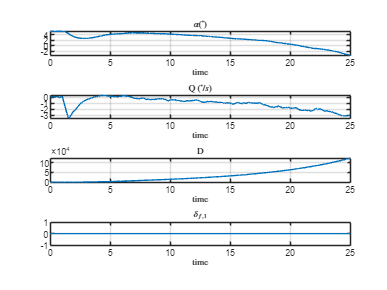

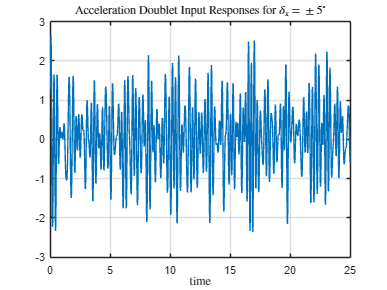

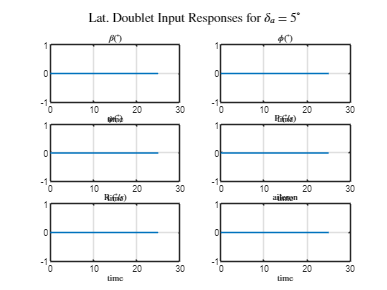

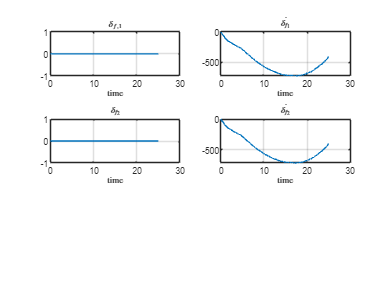

[y_all, time] = simulation(dt, t_total, angle, gust_velocities, k_command, c_r_command, c_c_command, delt_0_command, I_flap, true);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, gust_velocities, true)

f = 12.6404


flight_data.t = time(1:end-2);
flight_data.ax = diff(diff(convlength(y_all(:,10),"ft","m"))); % techanlly this assumes vehcile axis aligned with intertial axies (not strictly true)
flight_data.ay = diff(diff(convlength(y_all(:,11),"ft","m")));
flight_data.az = diff(diff(convlength(y_all(:,12),"ft","m")));
flight_data.fs = 1/dt; %saming frequencey
save("flightData_Rigid", "flight_data");

% % sys = ssest([time; y_all(1)],2)
% sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2)
% frsys = idfrd(sys)
% % bode(frsys)
% figure;
% spectrum(frsys)

## Perform optimization

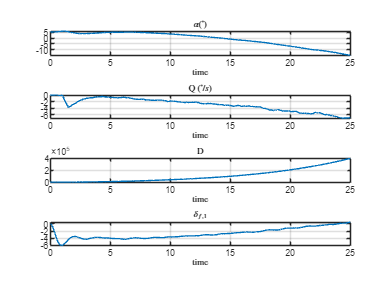

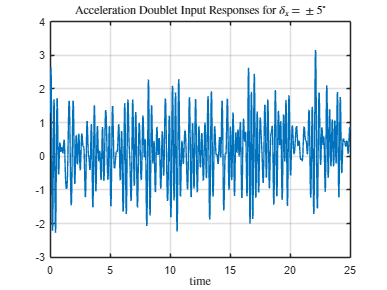

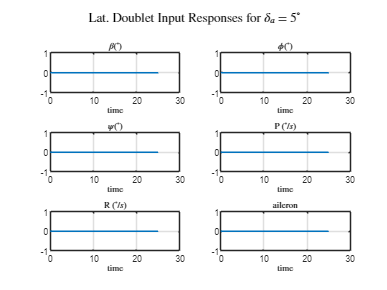

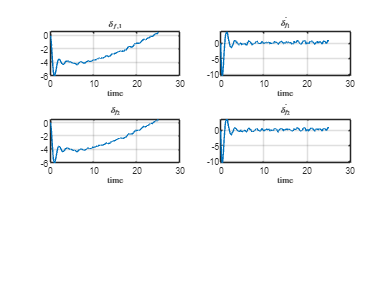

[y_all, time] = simulation(dt, t_total, angle, gust_velocities, x_0(1), x_0(2), x_0(3), x_0(4), x_0(5), false);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, gust_velocities, false)

f = 13.0320


flight_data.t = time(1:end-2);
flight_data.ax = diff(diff(convlength(y_all(:,10),"ft","m"))); % techanlly this assumes vehcile axis aligned with intertial axies (not strictly true)
flight_data.ay = diff(diff(convlength(y_all(:,11),"ft","m")));
flight_data.az = diff(diff(convlength(y_all(:,12),"ft","m")));
flight_data.fs = 1/dt; %saming frequencey
save("flightData_UnOpt", "flight_data");

% Define the objective function
obv_fun = @(x) objective_function(x, dt, t_total, angle,  gust_velocities, false);

% Define the initial design variables

% Define the bounds for the design variables
% lb = [0, 0, .004, -1e1, 1e-6];
% ub = [1e1, 1e1, 1e1, 1e1, 1e1];
%good for timming
% lb = [-5e1, 0, .0004, -1e2, 1e-9];
% ub = [5e1, 5e1, .0005, 1e2, 5e1];
%for ride quality
% lb = [-5e2, 0, .0004, -1e3, 1e-9];
% ub = [5e2, 5e3, .0005, 1e3, 5e2];
%for ride quality inc;uding delta_0
lb = [-5e2, 0, .0004, -1e2, 1e-9];
ub = [5e2, 5e3, .0005, 1e2, 5e2];
% avoid delta 0
lb = [-5e2, 0, .0004, -1e1, 1e-9];
ub = [5e2, 5e3, .0005, 1e1, 5e2];


% GA parameters - origianl
pop_size = 3; % Population size
max_generations = 4; % Number of generations
mutation_rate = 0.1; % Mutation rate
elite_size = 1; % Number of elite members to retain

% new GA paramters
pop_size = 100; % Population size
max_generations = 40; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 3; % Number of elite members to retain

pop_size = 50; % Population size
max_generations = 20; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 5; % Number of elite members to retain

pop_size = 20; % Population size
max_generations = 20; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 1; % Number of elite members to retain

% Initialize population
population = repmat(lb, pop_size, 1) + rand(pop_size, numel(lb)) .* repmat(ub - lb, pop_size, 1);

% Main GA loop
for generation = 1:max_generations
    % Evaluate fitness of each individual
    fitness = zeros(pop_size, 1);
    % Generate Dryden gust velocities
    % [ug_train, vg_train, wg_train] = generate_dryden_gust(time, altitude, v_avg, turbulence_intensity, 1/dt);
    % vg_train = zeros(size(ug));
    [ug_train, vg_train, wg_train, pg_train, qg_train, rg_train] = generate_dryden_gust_with_rotational( ...
        time, altitude, v_avg, windspeed_20ft, "severe", b/2, 1/dt_turbulence);
    vg_train = zeros(size(ug));
    pg_train = zeros(size(ug));
    rg_train = zeros(size(ug));
    
    % gust_velocities = [ug;vg;wg];
    gust_velocities_train = [ug_train; vg_train; wg_train; pg_train; qg_train; rg_train];
    gust_velocities_train(1:3,:) = convvel(gust_velocities_train(1:3,:), "m/s", "ft/s");

    gust_velocities_train = resample(gust_velocities_train', dt_turbulence/dt,1)'; % resample from 10Hz (as required by the mil spec) to the simulation rate 100Hz
    gust_velocities_train = gust_velocities; % this isa massively cheatrting because its overfitting

    parfor i = 1:pop_size
        % fitness(i) = objective_function(population(i, :), dt, t_total, angle, ug_train, vg_train, wg_train, disable_PAH); % printing this is good to track progress
        fitness(i) = objective_function(population(i, :), dt, t_total, angle, gust_velocities_train, disable_PAH); % printing this is good to track progress
        % fitness(i) = objective_function(population(i, :), dt, t_total, angle, ug, vg, wg, disable_PAH); % printing this is good to track progress
    end
    
    % Elitist selection
    [sorted_fitness, sorted_indices] = sort(fitness);
    elite_population = population(sorted_indices(1:elite_size), :);
    
    % Select individuals based on fitness (roulette wheel selection)
    fitness_sum = sum(fitness);
    fitness_prob = fitness / fitness_sum;
    selected_indices = randsample(1:pop_size, pop_size - elite_size, true, fitness_prob);
    selected_population = population(selected_indices, :);
    
    % Apply crossover and mutation
    new_population = selected_population;
    for i = 1:2:(pop_size - elite_size)
        if i+1 > (pop_size - elite_size), break; end
        % Crossover
        crossover_point = randi(numel(lb) - 1);
        new_population(i, crossover_point+1:end) = selected_population(i+1, crossover_point+1:end);
        new_population(i+1, crossover_point+1:end) = selected_population(i, crossover_point+1:end);
        
        % Mutation
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i+1, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
    end
    
    % Update population with elite members
    population = [elite_population; new_population];
    
    % Display progress
    disp(['Generation: ', num2str(generation), ', Best Fitness: ', num2str(min(sorted_fitness))]);
end

Generation: 1, Best Fitness: 11.9834
Generation: 2, Best Fitness: 11.9827
Generation: 3, Best Fitness: 11.9733
Generation: 4, Best Fitness: 11.9733
Generation: 5, Best Fitness: 11.9733
Generation: 6, Best Fitness: 11.9625
Generation: 7, Best Fitness: 11.9625
Generation: 8, Best Fitness: 11.9625
Generation: 9, Best Fitness: 11.9625
Generation: 10, Best Fitness: 11.9625
Generation: 11, Best Fitness: 11.9625
Generation: 12, Best Fitness: 11.9625
Generation: 13, Best Fitness: 11.9625
Generation: 14, Best Fitness: 11.9625
Generation: 15, Best Fitness: 11.9558
Generation: 16, Best Fitness: 11.9558
Generation: 17, Best Fitness: 11.9558
Generation: 18, Best Fitness: 11.9558
Generation: 19, Best Fitness: 11.952
Generation: 20, Best Fitness: 11.952



% Find the best solution
x_opt = elite_population(1, :);
f_opt = sorted_fitness(1);

% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); 

 -417.5551  473.1104    0.0005   -9.2379   13.2850



disp('Optimal objective function value:');

Optimal objective function value:


disp(f_opt);

   11.9520





% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); disp('Optimal objective function value:');

 -417.5551  473.1104    0.0005   -9.2379   13.2850

Optimal objective function value:


disp(f_opt);

   11.9520



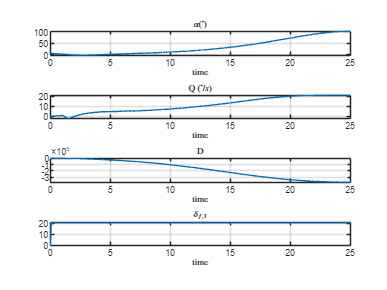

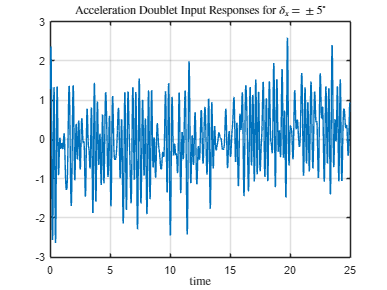

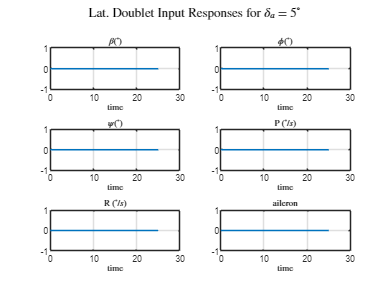

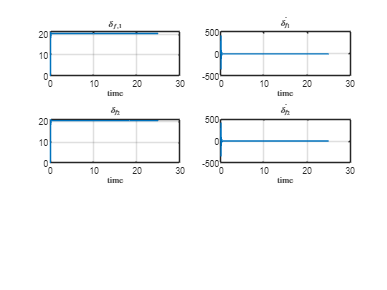


[y_all, time] = simulation(dt, t_total, angle, gust_velocities, x_opt(1), x_opt(2), x_opt(3), x_opt(4), x_opt(5), false);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_opt, dt, t_total, angle, gust_velocities, false)

f = 11.9520


flight_data.t = time(1:end-2)

flight_data = struct with fields:
     t: [2499×1 double]
    ax: [2499×1 double]
    ay: [2499×1 double]
    az: [2499×1 double]
    fs: 100


flight_data.ax = diff(diff(convlength(y_all(:,10),"ft","m"))) % techanlly this assumes vehcile axis aligned with intertial axies (not strictly true)

flight_data = struct with fields:
     t: [2499×1 double]
    ax: [2499×1 double]
    ay: [2499×1 double]
    az: [2499×1 double]
    fs: 100


flight_data.ay = diff(diff(convlength(y_all(:,11),"ft","m")))

flight_data = struct with fields:
     t: [2499×1 double]
    ax: [2499×1 double]
    ay: [2499×1 double]
    az: [2499×1 double]
    fs: 100


flight_data.az = diff(diff(convlength(y_all(:,12),"ft","m")))

flight_data = struct with fields:
     t: [2499×1 double]
    ax: [2499×1 double]
    ay: [2499×1 double]
    az: [2499×1 double]
    fs: 100


flight_data.fs = 1/dt; %saming frequencey
save("flightData_AC", "flight_data");

function [y_all, time] = simulation(dt, t_total, angle, gust_velocities, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH)
    % define IC and controls
    time = [0:dt:t_total]';
    t_0 = 1;
    t_end = length(time);

    % gust velociteis
    ug = gust_velocities(1,:);
    vg = gust_velocities(2,:);
    wg = gust_velocities(3,:);
    
    %elevator trim angle
    delta_e_trim = deg2rad(-1.3683881539243);
    delta_e_trim = deg2rad(0);
    alpha_trim = deg2rad(5.38766545134696);%+deg2rad(2);


    throttle = zeros(size(time));
    elevator = ones(size(time))* deg2rad(delta_e_trim);
    aileron = zeros(size(time));
    rudder = zeros(size(time));
    elevator(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180 + deg2rad(delta_e_trim);
    %aileron(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180;
    
    k = ones(size(time)) .* k_command; % PAH spring const
    c_r = ones(size(time)) .* c_r_command; % rate damping coefficient (N*s/rad^2)
    c_c = ones(size(time)) .* c_c_command; % coulomb damping coefficient (N*s/rad^2)
    %delta_0 = zeros(size(time)); % commanded deflection (radians)
    delta_0 = ones(size(time)) .* delt_0_command; % commanded deflection (radians)
    % colombic damping coefficient (N)pm
    
    %k = k + .03*randn(size(time));
    %delta_0 = delta_0 + .003*randn(size(time));
    
    
    % elevator(1.5/dt:2/dt) = ones(size(1.5/dt:2/dt)).*angle.*-pi./180.;
    % elevator = elevator  + .003*randn(size(elevator));
    VT = zeros(size(time));
    VT(1) = convvel(487.542331889981,"kts","ft/s");
    Alphaest = ones(size(time))*alpha_trim; % if i starrt thisa a number that is not trim then i get the response to an alpha disturbance
    Betaest = zeros(size(time));
    phi = zeros(size(time));
    theta = zeros(size(time));
    theta = ones(size(time))*alpha_trim;
    psi = zeros(size(time));
    P = zeros(size(time));
    Q = zeros(size(time));
    R = zeros(size(time));
    ned = [zeros(size(time)),zeros(size(time)),zeros(size(time))];
    delta_f_1 = 0; % inital flap 1 position
    delta_f_dot_1 = 0; % initial flap 1 rate
    delta_f_2 = 0; % inital flap 2 position
    delta_f_dot_2 = 0; % initial flap 2 rate

    % try this
    % delta_f_1 = delt_0_command; % inital flap 1 position
    % delta_f_dot_1 = 0; % initial flap 1 rate
    % delta_f_2 = delt_0_command; % inital flap 2 position
    % delta_f_dot_2 = 0; % initial flap 2 rate
    
    cv = [throttle,   elevator ,   aileron  ,   rudder, k, c_r, delta_0, c_c];
    X_0 = [VT(1), Alphaest(1), Betaest(1), phi(1), theta(1), psi(1), ...
        P(1), Q(1), R(1), ned(1,1), ned(1,2), -ned(1,3), throttle(t_0), elevator(t_0) , ...
        aileron(t_0) , rudder(t_0),...
        delta_f_1, delta_f_dot_1, delta_f_2, delta_f_dot_2];
    
    y = X_0;
    
    %initialize y_all and t_all with IC as first element
    y_all = zeros([length(t_0:t_end),20]);       t_all = zeros([length(t_0:t_end),1]);
    y_all(1,:) = y;     t_all(1) = time(t_0);       J = 2;
    
    % produce dryden turbulence

    % % Dryden turbulence parameters (modify as needed)
    % altitude = convlength(46000,"ft","m");     % Initial altitude (m)
    % windspeed_20ft = 15;   % Wind speed at 20 ft (m/s)
    % turbulence_intensity = 'moderate'; % 'light', 'moderate', or 'severe'
    % 
    % % Generate Dryden gust velocities
    % [ug, vg, wg] = generate_dryden_gust(time, altitude, windspeed_20ft, turbulence_intensity);
    % %plot(time,convvel([ug; vg; wg], "m/s", "ft/s")); legend(["u_g", "v_g", "w_g"])

    for i = (t_0):(length(time)-1)
        cv1 = cv(i,:); %update control inputs and time span for ODE45 each iteration
    
        % PID controller for the PAH
        %k(demanded)
    
        tspan = [time(i) time(i+1)];       dt = time(i+1) - time(i);
        [t,y] = ode45(@(t,y) Aether_6DOF(t, y, cv1, gust_velocities(:,i), [], I_flap, disable_PAH), tspan, X_0);
        X_0 = y(size(y, 1),:);  % set new IC as ending state
        t_all(J) = t(end);       y_all(J,:) = y(end,:);
        J = J + 1; % indexer for recording y and t
    end
end

function f = objective_function(x, dt, t_total, angle, gust_velocities, disable_PAH)
    % unpack x
    k_command = x(1); c_r_command = x(2); c_c_command = x(3); delt_0_command = x(4); I_flap = x(5);

    % run simulation
    %[y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH);
    [y_all, time] = simulation(dt, t_total, angle, gust_velocities, k_command, c_r_command, 0, delt_0_command, I_flap, disable_PAH); % set couloub to 0

    % i dont think i need to do this but ben does it so i will keep it
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end

    % old objective function - works well for trimming an aircraft
    f = max(sqrt( diff(diff(Vname{10})).^2 + diff(diff(Vname{11})).^2 + diff(diff(Vname{12})).^2 ));
    
    % store the flight data
    flight_data.t = time(1:end-2);
    flight_data.ax = diff(diff(convlength(y_all(:,10),"ft","m"))); % techanlly this assumes vehcile axis aligned with intertial axies (not strictly true)
    flight_data.ay = diff(diff(convlength(y_all(:,11),"ft","m")));
    flight_data.az = diff(diff(convlength(y_all(:,12),"ft","m")));
    flight_data.fs = 1/dt; %saming frequencey
    
    % compute the ride qualtiy
    [rms_total, vdv_total, c_f] = ride_quality_analysis(flight_data, false);
    % make the object values as minimumizing sum of the discomfort metrics
    % f = rms_total + vdv_total + sum(c_f); % including y perturbations
    % f = rms_total + vdv_total + c_f(1) + c_f(3); % longitudinal only
    f = vdv_total;
end

function plot_6dof_results(y_all, time, angle)
    %Convert to deg
    y_all(:,2:end) = y_all(:,2:end)*180/pi;
    
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    
    % Plot Longitudinal variables (VT, VT_guid, theta, theta_guid, Q, del_t, del_e)
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end
    
    figure
    ii = 0;
    for i = [2,8,12,17] %7,9
        ii = ii + 1;
        subplot(4,1,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
        %title(['Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    end
    
    figure
    plot(time(1:end-2),diff(diff(Vname{12}))), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    title(['Acceleration Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    % latteral plots
    figure
    ii=0;
    for i = [3 4 6 7 9, 15]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end
    sgtitle(['Lat. Doublet Input Responses for $\delta_a$ = ', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    
    % PAH plots
    figure
    ii=0;
    for i = [17,18,19,20]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end

    % figure;
    % sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2);
    % frsys = idfrd(sys);
    % spectrum(frsys);
end